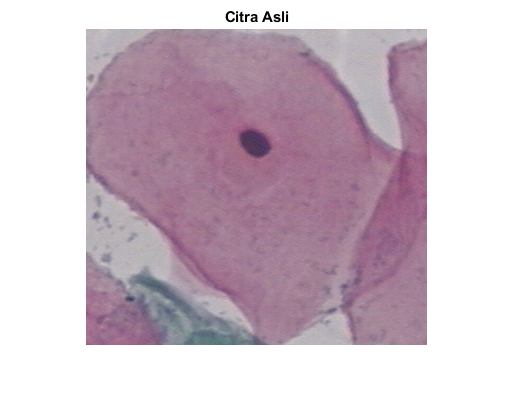

I = imread('Normal/157183193-157183241-001.bmp');
figure, imshow(I), title('Citra Asli');

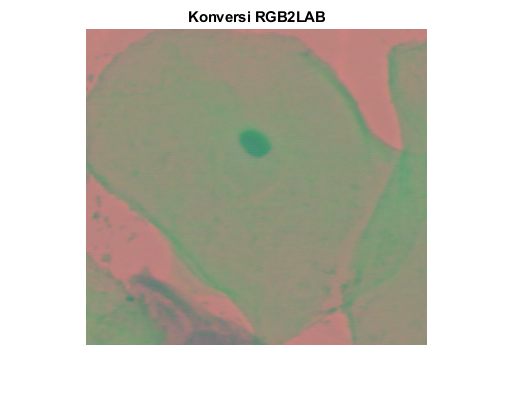

%% Convert RGB ke LAB
cform = makecform('srgb2lab');
lab_he = applycform(I,cform);
imshow(lab_he), title('Konversi RGB2LAB');

%% Klasifikasi ke dlm warna 'a*b*' dgn K-Means Clustering
ab = double(lab_he(:,:,2:3));
nrows = size(ab,1);
ncols = size(ab,2);
ab = reshape(ab,nrows*ncols,2);

nColors = 2; %k
% clustering diulang sebanyak 3 kali
[cluster_idx, cluster_center] = kmeans(ab,nColors,'distance','sqEuclidean', ...
                                      'Replicates',3);

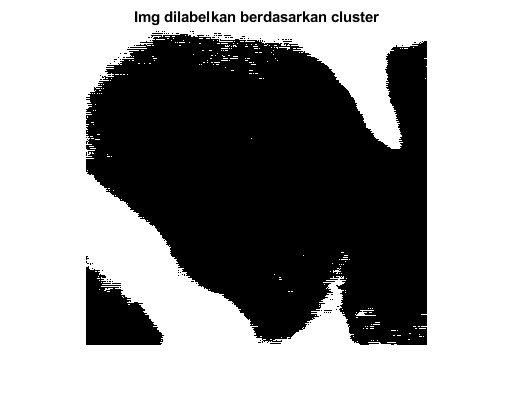

%% Melabelkan setiap pixel pada Citra Nukleus dgn K-Means
pixel_labels = reshape(cluster_idx,nrows,ncols);
figure, imshow(pixel_labels,[]), title('Img dilabelkan berdasarkan cluster');

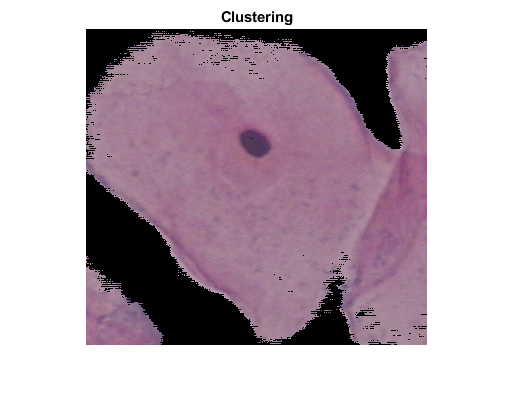

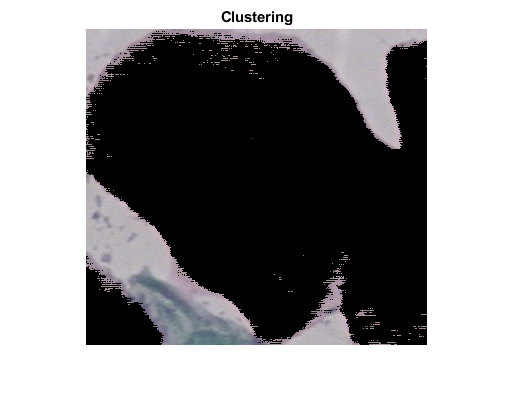

%% Membuat Gambar yang disegmentasi berdasarkan nilai warna nya (nColors) dgn iterasi tertentu
segmented_images = cell(1,3);
rgb_label = repmat(pixel_labels,[1 1 3]);

for k = 1:nColors
    color = I;
    color(rgb_label ~= k) = 0;
    segmented_images{k} = color;
    img = segmented_images{k};
    figure, imshow(img), title ('Clustering');
end

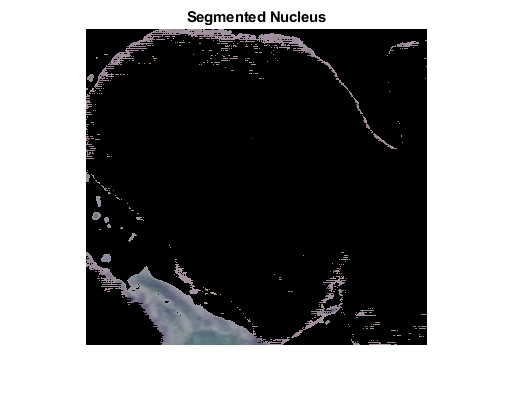

%% Segmentasi Nukleus ke dalam objek yang terpisah
mean_cluster_value = mean(cluster_center,2);
[tmp, idx] = sort(mean_cluster_value);
blue_cluster_num = idx(1);

L = lab_he(:,:,1);
blue_idx = find(pixel_labels == blue_cluster_num);
L_nukleus = L(blue_idx);
segment_nucleus = imbinarize(L_nukleus);

% segment_nucleus digunakan u/ melabelkan yang mana termasuk nucleus
nuclei_labels = repmat(uint8(0),[nrows ncols]);
nuclei_labels(blue_idx(segment_nucleus==false)) = 1;
nuclei_labels = repmat(nuclei_labels,[1 1 3]);
blue_nuclei = I;
blue_nuclei(nuclei_labels ~= 1) = 0;
figure, imshow(blue_nuclei), title('Segmented Nucleus');

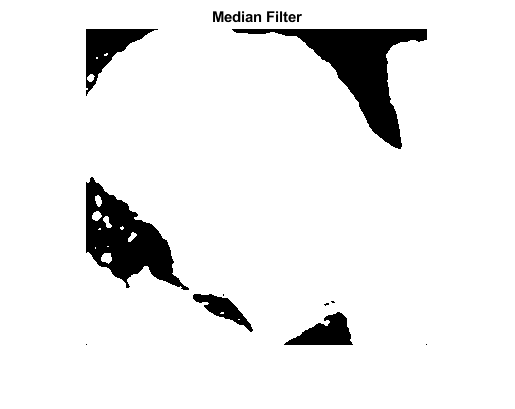



% Penghilangan Noise dengan Median Filter, bwareaopen
% dan pengisiian lubang pada objek (imfill)

BW = ~im2bw(I, 0.65);
BW2 = medfilt2(BW,[3 3]);
BW3 = bwareaopen(BW2, 65);
BW4= imfill(BW3, 'holes');

imshow(BW2), title ('Median Filter');

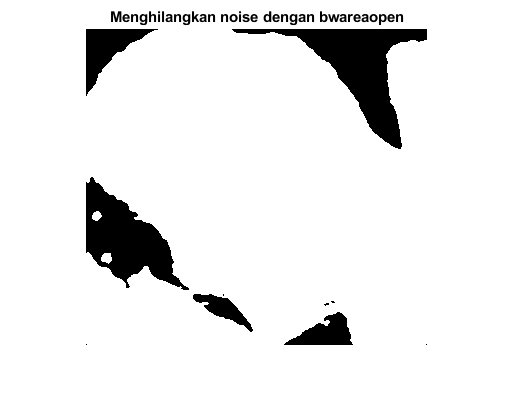

imshow(BW3), title ('Menghilangkan noise dengan bwareaopen');

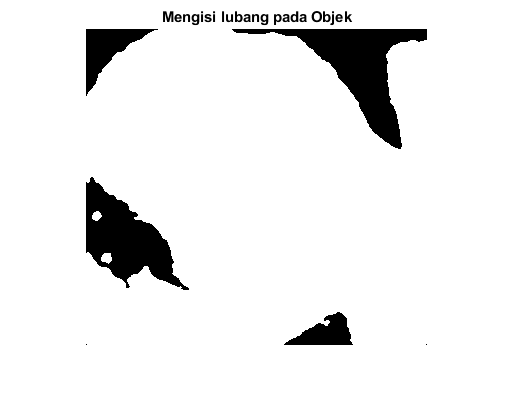

imshow(BW4), title ('Mengisi lubang pada Objek');



%% REGIONPROPS
%berikut menjalan fungsi regionprops tanpa parameter
%sehingga properti yang dihitung adalah 'Area','Centroid',
%dan 'BoundingBox'

S = regionprops(BW4, 'Centroid', 'BoundingBox', 'Area'); 
size(S) %menampilkan ukuran larik dari S

ans =      3     1


S %menampilkan struktur S

S = 3×1 struct array with fields:
    Area
    Centroid
    BoundingBox


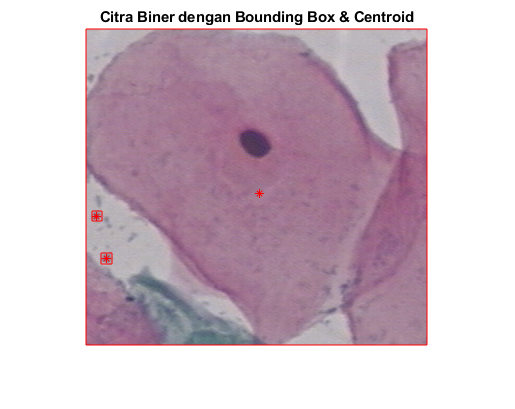

ans =     'Banyaknya Pixel objek ke 1 = 92636 _dengan centroid[1.737122e+02 1.645237e+02]
     '


ans =     'Banyaknya Pixel objek ke 2 = 71 _dengan centroid[1.123944e+01 1.875211e+02]
     '


ans =     'Banyaknya Pixel objek ke 3 = 91 _dengan centroid[2.120879e+01 2.295385e+02]
     '



figure;imshow(I), title('Citra Biner dengan Bounding Box & Centroid'); %menampilkan citra biner
hold on ; %tetap mengaktifan figur citra biner di atas

%----------------------------------------------- 
%untuk Menggambar kotak terkecil yang melingkupi Objek
%dengan fungsi rectangle warna garis dengan kotak merah (red)
for i=1:size(S,1)
    rectangle('Position', S(i).BoundingBox,'edgecolor','red');
    
    %Menggambar posisi centroid setiap objek
    plot(S(i).Centroid(1),S(i).Centroid(2),'r*');
    
    %Mencetak banyaknya pixel dan posisi centroid setiap objek
    sprintf('Banyaknya Pixel objek ke %d = %d _dengan centroid[%d %d]\n',i, S(i).Area,..._
    S(i).Centroid(1), S(i).Centroid(2))

end

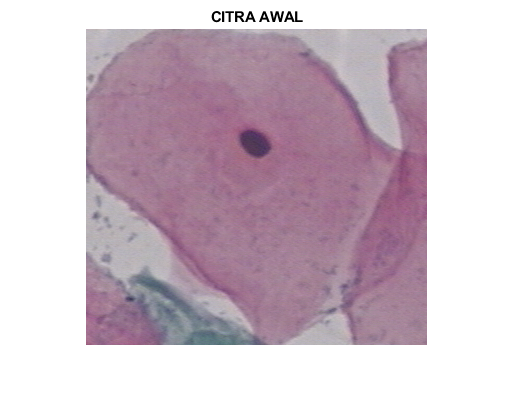



%% LABELING dengan WARNA
%setiap objek akan diberi label berbeda
%pixel pada satu objek akan diberi label yang sama
%pixel pada objek berbeda akan diberi label berbeda 
%memberi label berbeda pada setiap objek
CC = bwconncomp(BW4);

L = labelmatrix(CC);
 
%setiap objek akan diberi warna RGB
IL = label2rgb(L);

%menampilkan citra awal
figure, imshow(I), title('CITRA AWAL');

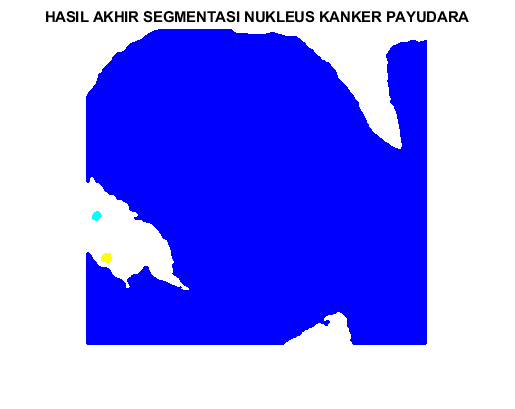


%menampilkan gambar berwarna RGB
figure;imshow(IL), title ('HASIL AKHIR SEGMENTASI NUKLEUS KANKER PAYUDARA');